clc;clear
nvar = 2;
lb = [0 -5];
ub = [5 0];

gamultiobj stopped because the average change in the spread of Pareto solutions is less than options.FunctionTolerance.


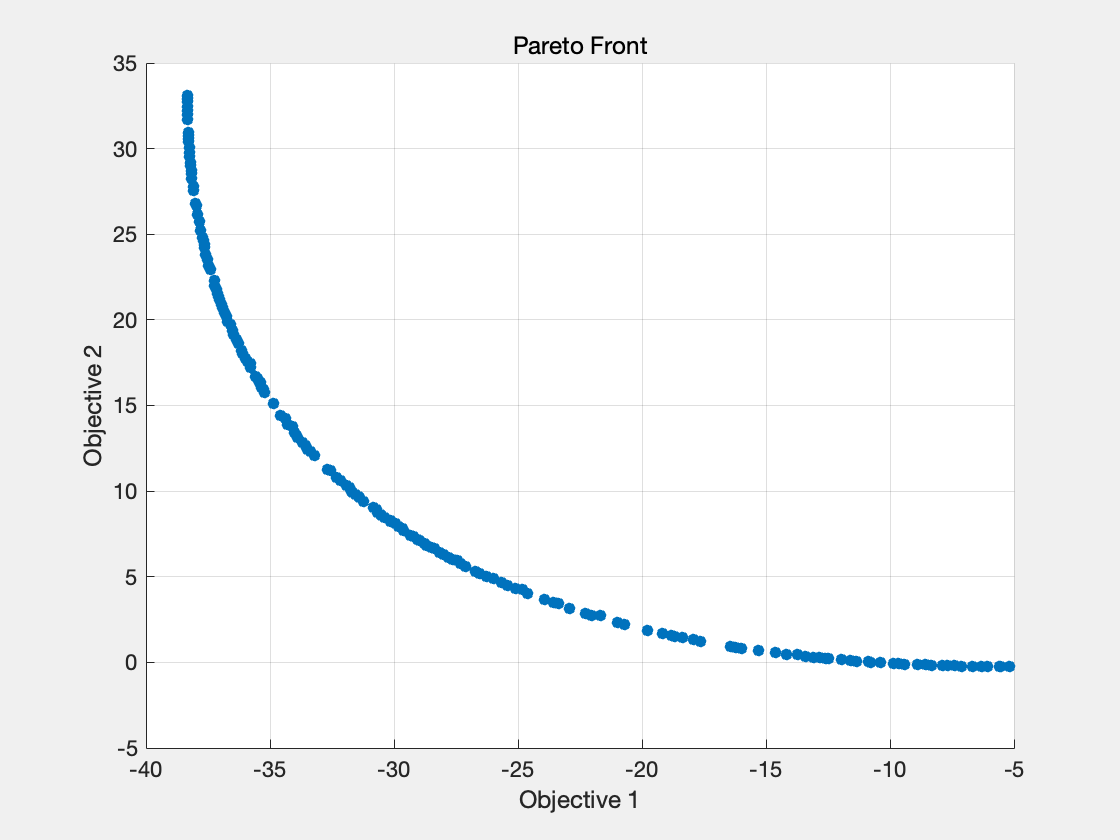

% 设置非默认求解器选项
options = optimoptions("gamultiobj","PopulationSize",500,"PlotFcn",...
    "gaplotpareto");

% 求解
[solution,objectiveValue] = gamultiobj(@mymulti1,nvar,[],[],[],[],lb,ub,[],...
    [],options);


% 清除变量
clearvars options
function f = mymulti1(x)

f(2) = x(1)^4 + x(2)^4 + x(1)*x(2) - (x(1)*x(2))^2;
f(1) = f(2) - 10*x(1)^2;
end
